# Sample Motif Sides Demo

## Initial Housekeeping

%clear previous outputs
clear all;
close all;
clc;

%Manually setting some color values here, this requires access to the file 'distinguishable_colors.m'
colors = distinguishable_colors(15);
ColorDark= colors(1,:);
ColorMiddle= colors(2,:);
ColorLight= colors(3,:);

## File Detail Inputs for Synthetic Series

disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      Inputs')

      Inputs


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


Synthetic_Motif_Side_Demo_TSFileName  = "Synthetic_Motif_Side_Demo"

Synthetic_Motif_Side_Demo_TSFileName = "Synthetic_Motif_Side_Demo"


%Add path to folder that contains sample input series
TSFilePath  = "......\" %\" needed at end of path

TSFilePath = "C:\Users\eoinc\Dropbox\PHD\Motif_Disc_Models\SAX_Matlab\ITISE_Special_Edition_Paper_2022_Reviewer_Changes_Draft_1\Scripts_For_Publication\Input_Series\"

TSFileExt   = ".xlsx"

TSFileExt = ".xlsx"

## Add path to Matrix Profile Matlab Code Here

%Add path to your folder that contains Keogh Matlab MP code here
%Available at https://www.cs.ucr.edu/~eamonn/MatrixProfile.html
addpath('.......');

## Matrix Profile Run Inputs

% %Motif Length Inputs
% SetMotifLength = 50
% blnUseMotifRange = 0
% MinMotifLength = 50
% MaxMotifLength = 150
% blnUseMotifLengthStepSize = 1
% MotifLengthStepSize = 50
% %Date Inputs
% blnUseDateRange = 0
% DateFrom = datetime('01-Jan-2007')
% DateTo = datetime('01-Jan-2011')

## Create Generalised Variables

%Flags
blnShowOrigPlots = 1;
blnShowNormalisedPlots = 0;
blnShowMatrixProfilePlots = 1;

%Date Inputs
blnUseDateRange = 0;
DateFrom = datetime('01-Jan-2007');
DateTo = datetime('01-Jan-2011');

%Create Plot Axes
PltXAxis = "Date";
PltYAxis = "Rate";

## Create Motif Side Demo Plot

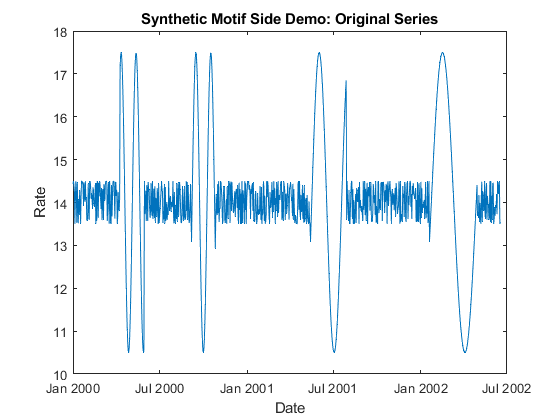

Synthetic_Motif_Side_Demo_RawData = InFileToTimeTable(Synthetic_Motif_Side_Demo_TSFileName, TSFilePath, TSFileExt, blnShowOrigPlots,blnShowNormalisedPlots,blnUseDateRange,DateFrom,DateTo,PltXAxis,PltYAxis);

disp('Known motif values from file')

Known motif values from file


Motif_1_SideA_StartIdx = 100

Motif_1_SideA_StartIdx =    100

Motif_1_SideA_EndIdx = 150

Motif_1_SideA_EndIdx =    150

Motif_1_SideB_StartIdx = 250

Motif_1_SideB_StartIdx =    250

Motif_1_SideB_EndIdx = 300

Motif_1_SideB_EndIdx =    300


Motif_1_Max_Length = 50

Motif_1_Max_Length =     50


Motif_2_SideA_StartIdx = 500

Motif_2_SideA_StartIdx =    500

Motif_2_SideA_EndIdx = 575

Motif_2_SideA_EndIdx =    575

Motif_2_SideB_StartIdx = 749

Motif_2_SideB_StartIdx =    749

Motif_2_SideB_EndIdx = 850

Motif_2_SideB_EndIdx =    850


Motif_2_Max_Length = 100

Motif_2_Max_Length =    100


%Get Motif Pair 1 data for each side
Motif_1_SideA = Synthetic_Motif_Side_Demo_RawData(Motif_1_SideA_StartIdx:Motif_1_SideA_EndIdx,"Rate");
Motif_1_SideB =  Synthetic_Motif_Side_Demo_RawData(Motif_1_SideB_StartIdx:Motif_1_SideB_EndIdx,"Rate");

%Get Motif Pair 2 data for each side
Motif_2_SideA = Synthetic_Motif_Side_Demo_RawData(Motif_2_SideA_StartIdx:Motif_2_SideA_EndIdx,"Rate");
Motif_2_SideB = Synthetic_Motif_Side_Demo_RawData(Motif_2_SideB_StartIdx:Motif_2_SideB_EndIdx,"Rate"); 
 
%Get Series length
[Series_Length,NA] = size(Synthetic_Motif_Side_Demo_RawData);

%-----------------------------------
%For display of Raw data with motif sections highlighted need to break up
%raw series into segments and stitch them together with different colors in
%the plot itself
%
% We can't use plot() for this need to use line()
%
%-----------------------------------
%
%   Y Vals come from The Raw Series 
%
%From Raw Series Start (i.e. 0) to Motif_1_SideA_StartIdx
Raw_Series_Segment_1 = Synthetic_Motif_Side_Demo_RawData(1:Motif_1_SideA_StartIdx - 1,"Rate");
%Motif_1_SideA covered above
%From end of Motif_1_SideA to start of Motif_1_SideB 
Raw_Series_Segment_2 = Synthetic_Motif_Side_Demo_RawData(Motif_1_SideA_EndIdx + 1:Motif_1_SideB_StartIdx - 1,"Rate");
%Motif_1_SideB covered above
%From end of Motif_1_SideB to start of Motif_2_SideA
Raw_Series_Segment_3 = Synthetic_Motif_Side_Demo_RawData(Motif_1_SideB_EndIdx + 1:Motif_2_SideA_StartIdx - 1,"Rate");
%Motif_2_SideA covered above
%From end of Motif_2_SideA to start of Motif_2_SideB 
Raw_Series_Segment_4 = Synthetic_Motif_Side_Demo_RawData(Motif_2_SideA_EndIdx + 1:Motif_2_SideB_StartIdx - 1,"Rate");
%Motif_2_SideB covered above
%From end of Motif_1_SideB to end of series
Raw_Series_Segment_5 = Synthetic_Motif_Side_Demo_RawData(Motif_2_SideB_EndIdx + 1:Series_Length,"Rate");
%
%   X Vals come from The Raw Series Indexes (including Motif side locations) 
%
%From Raw Series Start (i.e. 0) to Motif_1_SideA_StartIdx
Raw_Series_Segment_1_XVals = (1:Motif_1_SideA_StartIdx - 1);
%Motif_1_SideA 
Motif_1_SideA_XVals =  (Motif_1_SideA_StartIdx:Motif_1_SideA_EndIdx); 
%From end of Motif_1_SideA to start of Motif_1_SideB 
Raw_Series_Segment_2_XVals = (Motif_1_SideA_EndIdx + 1:Motif_1_SideB_StartIdx - 1);
%Motif_1_SideB
Motif_1_SideB_XVals =  (Motif_1_SideB_StartIdx:Motif_1_SideB_EndIdx); 
%From end of Motif_1_SideB to start of Motif_2_SideA
Raw_Series_Segment_3_XVals = (Motif_1_SideB_EndIdx + 1:Motif_2_SideA_StartIdx - 1);
%Motif_2_SideA 
Motif_2_SideA_XVals =  (Motif_2_SideA_StartIdx:Motif_2_SideA_EndIdx); 
%From end of Motif_2_SideA to start of Motif_2_SideB 
Raw_Series_Segment_4_XVals = (Motif_2_SideA_EndIdx + 1:Motif_2_SideB_StartIdx - 1);
%Motif_2_SideB
Motif_2_SideB_XVals =  (Motif_2_SideB_StartIdx:Motif_2_SideB_EndIdx); 
%From end of Motif_1_SideB to end of series
Raw_Series_Segment_5_XVals = (Motif_2_SideB_EndIdx + 1:Series_Length);

## Plotting full series with Motifs Highlighted

disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      Showing Full series with Motif Pairs highlighted')

      Showing Full series with Motif Pairs highlighted


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


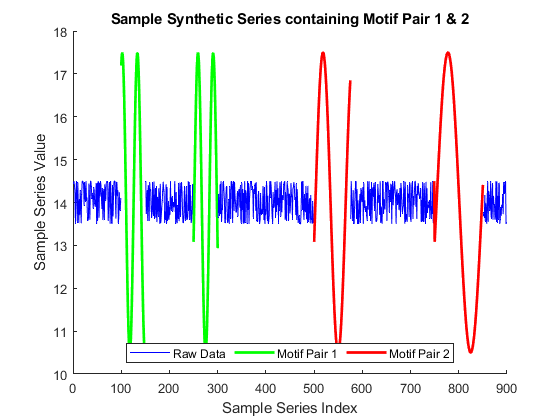

Full_Series_With_Motifs_Highlighted=figure();
hold on
    h1 = line(Raw_Series_Segment_1_XVals,Raw_Series_Segment_1.Rate,'Color',ColorDark);  hold on
    h2 = line(Motif_1_SideA_XVals,Motif_1_SideA.Rate,'Color',ColorLight,'LineWidth',2); hold on
    line(Raw_Series_Segment_2_XVals,Raw_Series_Segment_2.Rate,'Color',ColorDark);  hold on
    line(Motif_1_SideB_XVals,Motif_1_SideB.Rate,'Color',ColorLight,'LineWidth',2); hold on
    line(Raw_Series_Segment_3_XVals,Raw_Series_Segment_3.Rate,'Color',ColorDark); hold on
    h3 = line(Motif_2_SideA_XVals,Motif_2_SideA.Rate,'Color','red','LineWidth',2); hold on
    line(Raw_Series_Segment_4_XVals,Raw_Series_Segment_4.Rate,'Color',ColorDark); hold on
    line(Motif_2_SideB_XVals,Motif_2_SideB.Rate,'Color','red','LineWidth',2); hold on
    line(Raw_Series_Segment_5_XVals,Raw_Series_Segment_5.Rate,'Color',ColorDark); hold on
  
    strRawSeriesLegend = "Raw Data";
    strMotif1Legend = "Motif Pair 1";
    strMotif2Legend = "Motif Pair 2";
    %legend({strRawSeriesLegend,strMotif1Legend,strMotif2Legend})     
    
    legend([h1(1), h2(1), h3(1)], strRawSeriesLegend, strMotif1Legend,strMotif2Legend,'Orientation','horizontal','Location','south')
    legend show;

    xlabel('Sample Series Index') 
    ylabel('Sample Series Value') 

    title('Sample Synthetic Series containing Motif Pair 1 & 2');
hold off

## Along With individual Motifs

disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      Showing Individual Motif Pairs')

      Showing Individual Motif Pairs


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


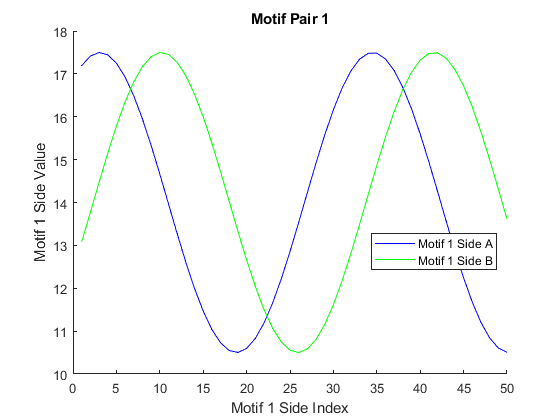

Motif_1_Side_A_And_B=figure();
hold on 
    plot(Motif_1_SideA.Rate,'Color',ColorDark,'DisplayName','Motif 1 Side A');
    plot(Motif_1_SideB.Rate,'Color',ColorLight,'DisplayName','Motif 1 Side B');
    
    legend('Location','best','color','white');
    legend show;
    
    xlabel('Motif 1 Side Index') 
    ylabel('Motif 1 Side Value') 

    title('Motif Pair 1');
    
    axis([0 Motif_1_Max_Length 10 18])
hold off

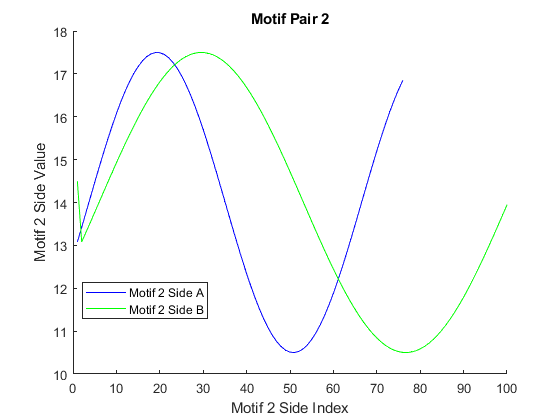


Motif_2_Side_A_And_B=figure();
hold on 
    plot(Motif_2_SideA.Rate,'Color',ColorDark,'DisplayName','Motif 2 Side A');
    plot(Motif_2_SideB.Rate,'Color',ColorLight,'DisplayName','Motif 2 Side B');
    
    legend('Location','best','color','white');
    legend show;
    
    xlabel('Motif 2 Side Index') 
    ylabel('Motif 2 Side Value') 

    title('Motif Pair 2');
    
    axis([0 Motif_2_Max_Length 10 18])
hold off

## Finally Plotting for Paper Diagram

disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      Display As Stack plot')

      Display As Stack plot


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


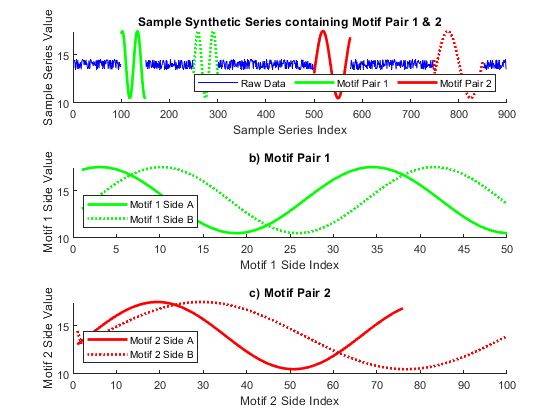

tiledlayout(3,1) % Requires R2019b or later
nexttile
hold on
    h1 = line(Raw_Series_Segment_1_XVals,Raw_Series_Segment_1.Rate,'Color',ColorDark);  hold on
    h2 = line(Motif_1_SideA_XVals,Motif_1_SideA.Rate,'Color',ColorLight,'LineWidth',2); hold on
    line(Raw_Series_Segment_2_XVals,Raw_Series_Segment_2.Rate,'Color',ColorDark);  hold on
    line(Motif_1_SideB_XVals,Motif_1_SideB.Rate,'Color',ColorLight,'LineWidth',2,'LineStyle',':'); hold on
    line(Raw_Series_Segment_3_XVals,Raw_Series_Segment_3.Rate,'Color',ColorDark); hold on
    h3 = line(Motif_2_SideA_XVals,Motif_2_SideA.Rate,'Color','red','LineWidth',2); hold on
    line(Raw_Series_Segment_4_XVals,Raw_Series_Segment_4.Rate,'Color',ColorDark); hold on
    line(Motif_2_SideB_XVals,Motif_2_SideB.Rate,'Color','red','LineWidth',2,'LineStyle',':'); hold on
    line(Raw_Series_Segment_5_XVals,Raw_Series_Segment_5.Rate,'Color',ColorDark); hold on
    
    strRawSeriesLegend = "Raw Data";
    strMotif1Legend = "Motif Pair 1";
    strMotif2Legend = "Motif Pair 2";
    legend([h1(1), h2(1), h3(1)], strRawSeriesLegend, strMotif1Legend,strMotif2Legend,'Orientation','horizontal','Location','south')  
  
    legend('Location','southeast','color','white');
    legend show;
    
    xlabel('Sample Series Index') 
    ylabel('Sample Series Value') 

    title('Sample Synthetic Series containing Motif Pair 1 & 2');
    
hold off

nexttile
hold on 
    plot(Motif_1_SideA.Rate,'Color',ColorLight,'LineWidth',2,'DisplayName','Motif 1 Side A');
    plot(Motif_1_SideB.Rate,'Color',ColorLight,'LineWidth',2,'LineStyle',':','DisplayName','Motif 1 Side B');
    
    legend('Location','southwest','color','white');
    legend show;
    
    xlabel('Motif 1 Side Index') 
    ylabel('Motif 1 Side Value') 

    title('b) Motif Pair 1');
    
    
    xlim([0 Motif_1_Max_Length])
hold off

nexttile
hold on 
    plot(Motif_2_SideA.Rate,'Color','red','LineWidth',2,'DisplayName','Motif 2 Side A');
    plot(Motif_2_SideB.Rate,'Color','red','LineWidth',2,'LineStyle',':','DisplayName','Motif 2 Side B');
    
    legend('Location','southwest','color','white');
    legend show;
    
    xlabel('Motif 2 Side Index') 
    ylabel('Motif 2 Side Value') 

    title('c) Motif Pair 2');
    
    xlim([0 Motif_2_Max_Length])
hold off

## Display Original Series

function ShowOriginalSeries(RawData,blnShowOrigPlots,blnShowNormalisedPlots,blnUseDateRange,DateFrom,DateTo,PltXAxis,PltYAxis,TSFileName)

    %Create text for plot titles
    strMainPlotTitleText = TSFileName; %Base off filename for now can change here later
    strMainPlotTitleText = strrep(strMainPlotTitleText,'_',' '); %Remove underscores if any   
    
    %Create Standard Plot Title Variables
    TSOrigSeriesPlotTitle = strMainPlotTitleText + ": Original Series";
    TSOrigSeriesNormalisedPlotTitle = strMainPlotTitleText + ": Normailsed Original Series";
    MatrixProfileSeriesPlotTitle = strMainPlotTitleText + ":  Matrix Profile";
    
    %Create Reduced (Date Range) Plot Title Variables
    TSReducedSeriesPlotTitle = strMainPlotTitleText + ": Reduced Series";
    TSReducedSeriesNormalisedPlotTitle = strMainPlotTitleText + ": Normalised Reduced Series";


    %Plot Original(s) if blnShowOrigPlots is set above
    TS_Orig_Series = RawData.Rate(:,1); 
    TS_Orig_Series_Norm =  normalize(TS_Orig_Series); 
    
    if blnShowOrigPlots == 1
        Orig_Series=figure;
        plot(RawData.Date,TS_Orig_Series)
        title(TSOrigSeriesPlotTitle)
        xlabel(PltXAxis) 
        ylabel(PltYAxis) 
    end   
    if blnShowNormalisedPlots == 1
        Orig_Series_Normalised=figure;
        %Also plot normalised series
        plot(RawData.Date,TS_Orig_Series_Norm)
        title(TSOrigSeriesNormalisedPlotTitle)
        xlabel(PltXAxis) 
        ylabel(PltYAxis) 
    end
    
    %Also handle data range
    if blnUseDateRange == 1        
        
        %First reduce the data according to date range specified above
        Range = timerange(DateFrom,DateTo);
        ReducedData = RawData(Range,:);
        TS_Reduced_Series = ReducedData.Rate(:,1);
        TS_Reduced_Series_Norm =  normalize(TS_Reduced_Series); 
        
        if blnShowOrigPlots == 1
            %Then plot
            Reduced_Series=figure;
            plot(ReducedData.Date,TS_Reduced_Series)
            title(TSReducedSeriesPlotTitle)
            xlabel(PltXAxis) 
            ylabel(PltYAxis)
        end
        if blnShowNormalisedPlots == 1
            %Also plot normalised series
            Reduced_Series_Normalised=figure;
            plot(ReducedData.Date,TS_Reduced_Series_Norm)
            title(TSReducedSeriesNormalisedPlotTitle)
            xlabel(PltXAxis) 
            ylabel(PltYAxis)
        end
            
    end
end

## Read Raw Data

function [RawData] = InFileToTimeTable(InFileName, TSFilePath, TSFileExt, blnShowOrigPlots,blnShowNormalisedPlots,blnUseDateRange,DateFrom,DateTo,PltXAxis,PltYAxis)
          
    %Input file details for debug of file read (if needed)
    %{
    opts = detectImportOptions(TSFileName);
    preview(TSFileName,opts)
    disp([opts.VariableNames' opts.VariableTypes'])
    %}
    
    %Create full filename including path for import
    TSFileName = TSFilePath + InFileName + TSFileExt; 
        
    %read into initial table and convert into timetable
    opts = detectImportOptions(TSFileName);
    RawData = readtable(TSFileName,opts);    
    RawData = table2timetable(RawData);
    
    %disp('---------------------------------------------------------------------------------')
    %disp('      Raw Data Summary for ' + TSFileName)
    %summary(RawData);
    %disp('---------------------------------------------------------------------------------')
    
    
    %Display Original Series (As selected by user)
    ShowOriginalSeries(RawData,blnShowOrigPlots,blnShowNormalisedPlots,blnUseDateRange,DateFrom,DateTo,PltXAxis,PltYAxis,InFileName)
end